% Clear the figure
clf;

% Define the transfer function
K =0

K = 0

sys = tf([1 1], [1 2 8 K]);

% Plot the root locus
rlocus(sys);
hold on;

% Define Zeta (dampening value)
zeta = 0.6

zeta = 0.6000

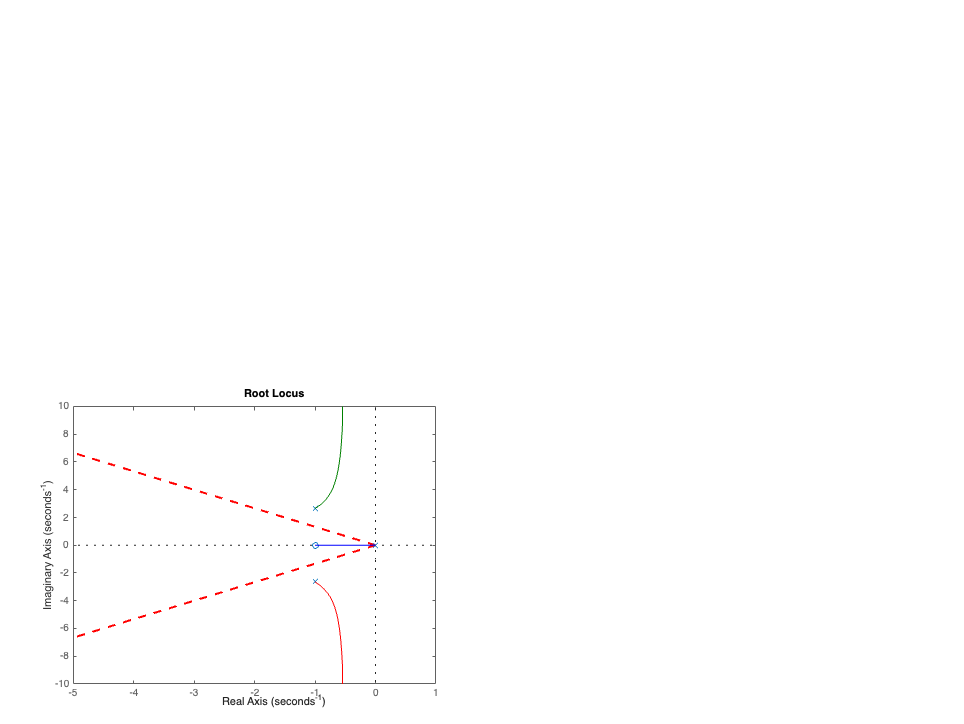


% Calculate the angle in radians
theta = acos(zeta);


% Calculate the coordinates for the line
radius = -100;
x = [0 radius * cos(theta)];  % X coordinates
y = [0 radius * sin(theta)];  % Y 

x_negative = [0 radius * cos(-theta)];  % X coordinates for -53 degrees
y_negative = [0 radius * sin(-theta)];  % Y

% Plot the line on the root locus plot
plot(x, y, '--', 'LineWidth', 2, 'Color', 'red');  % Dashed red line
plot(x_negative, y_negative, '--', 'LineWidth', 2, 'Color', 'red');  

% Set the limits of the plot to make sure everything fits well
axis equal;
xlim([-5 1]);
ylim([-10 10]);

% Hold off to end plotting
hold off;